**Divergent Starting (-1.8,-1.4)**

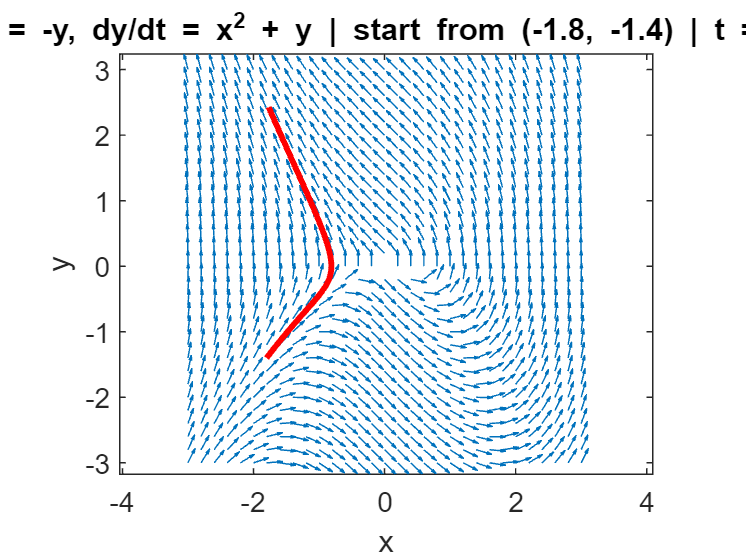

% Range
x = -3:0.2:3; 
y = -3:0.2:3;

% Grid
[X, Y] = meshgrid(x, y);

% System 
U = -Y;
V = X.^2 + Y;

% Normalize arrow length
arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

% Plot
figure
quiver(X, Y, U, V)
hold on

% Initial conditions
x0 = -1.8;
y0 = -1.4;

% Time span
tspan = [0, 3];

% System Definition
system = @(t, Y) [-Y(2); Y(1)^2 + Y(2)];

% ODE45 method
[~, Y] = ode45(system, tspan, [x0, y0]);

% Path
plot(Y(:,1), Y(:,2), 'r', 'LineWidth', 2)

axis equal

% Styling
title('dx/dt = -y, dy/dt = x^2 + y | start from (-1.8, -1.4) | t = [0, 3]')
xlabel('x')
ylabel('y')

hold off

**Divergent Starting (-1.7,-1.4)**

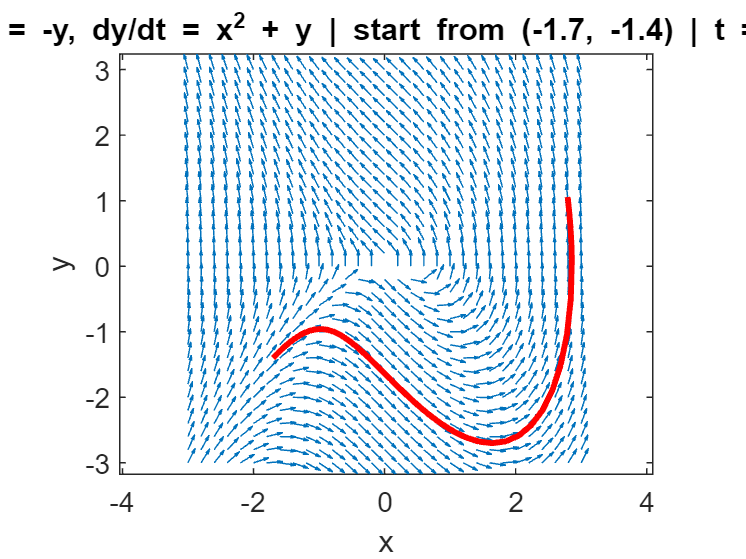

% Range
x = -3:0.2:3; 
y = -3:0.2:3;

% Grid
[X, Y] = meshgrid(x, y);

% System 
U = -Y;
V = X.^2 + Y;

% Normalize arrow length
arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

% Plot
figure
quiver(X, Y, U, V)
hold on

% Initial conditions
x0 = -1.7;
y0 = -1.4;

% Time span
tspan = [0, 3];

% System Definition
system = @(t, Y) [-Y(2); Y(1)^2 + Y(2)];

% ODE45 method
[~, Y] = ode45(system, tspan, [x0, y0]);

% Path
plot(Y(:,1), Y(:,2), 'r', 'LineWidth', 2)

axis equal

% Styling
title('dx/dt = -y, dy/dt = x^2 + y | start from (-1.7, -1.4) | t = [0, 3]')
xlabel('x')
ylabel('y')

hold off

**Divergent Starting (-1.7,-1.4) &  (-1.8,-1.4)**

% Range
x = -3:0.2:3; 
y = -3:0.2:3;

% Grid
[X, Y] = meshgrid(x, y);

% System 
U = -Y;
V = X.^2 + Y;

% Normalize arrow length
arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

% Plot
figure
quiver(X, Y, U, V)
hold on

% Initial conditions
x0 = -1.7;
y0 = -1.4;

i0 = -1.8;
j0 = -1.4;

% Time span
tspan = [0, 3];

% System Definition
system1 = @(t, Y) [-Y(2); Y(1)^2 + Y(2)];
system2 = @(t, K) [-K(2); K(1)^2 + K(2)];

% ODE45 method
[~, Y] = ode45(system1, tspan, [x0, y0]);
[~, K] = ode45(system2, tspan, [i0, j0]);

% Path
path1 = plot(Y(:,1), Y(:,2), 'r', 'LineWidth', 2)

path1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1.7000 -1.6355 -1.5740 -1.5152 -1.4588 -1.3735 -1.2925 -1.2151 -1.1402 -1.0671 -0.9950 -0.9231 -0.8505 -0.7766 -0.7004 -0.6211 -0.5380 -0.4500 -0.3564 -0.2563 -0.1487 -0.0329 0.0919 0.2263 0.3709 0.5259 0.6914 0.8669 1.0517 … ]
              YData: [-1.4000 -1.3332 -1.2732 -1.2194 -1.1714 -1.1064 -1.0541 -1.0136 -0.9845 -0.9662 -0.9585 -0.9615 -0.9750 -0.9993 -1.0345 -1.0809 -1.1388 -1.2084 -1.2897 -1.3828 -1.4872 -1.6022 -1.7269 -1.8593 -1.9971 -2.1370 -2.2746 -2.4045 … ]

  Show all propert

path2 = plot(K(:,1), K(:,2), 'g', 'LineWidth', 2)

path2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1.8000 -1.7478 -1.6981 -1.6508 -1.6057 -1.5231 -1.4477 -1.3787 -1.3155 -1.2574 -1.2041 -1.1551 -1.1100 -1.0687 -1.0308 -0.9962 -0.9647 -0.9362 -0.9107 -0.8879 -0.8680 -0.8510 -0.8368 -0.8257 -0.8176 -0.8129 -0.8116 -0.8141 … ]
              YData: [-1.4000 -1.3319 -1.2682 -1.2083 -1.1521 -1.0512 -0.9612 -0.8805 -0.8077 -0.7417 -0.6815 -0.6262 -0.5751 -0.5275 -0.4827 -0.4403 -0.3997 -0.3605 -0.3222 -0.2843 -0.2464 -0.2081 -0.1688 -0.1282 -0.0856 -0.0405 0.0076 0.0597 0.1163 … ]

  Show all pro

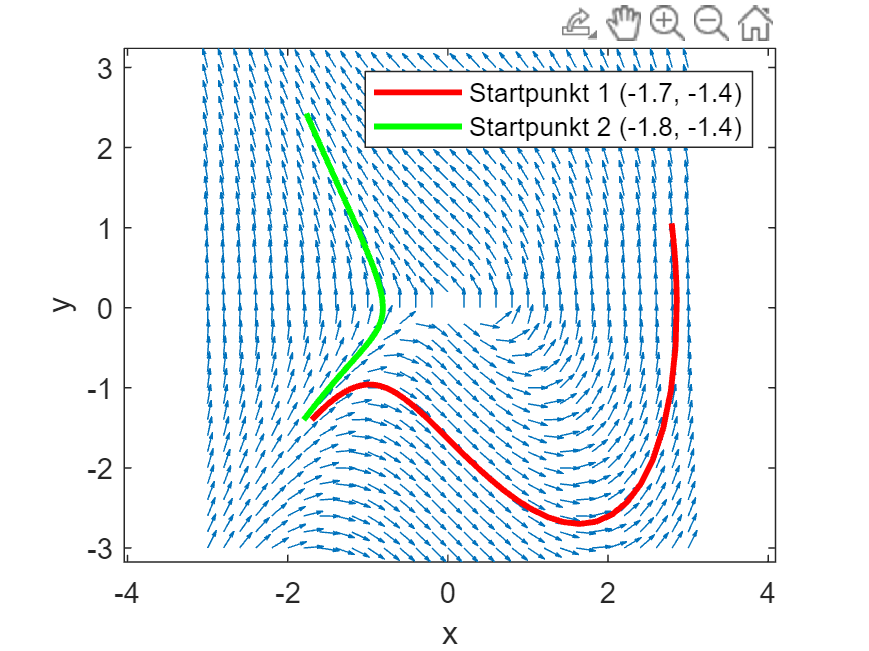


axis equal

% Styling
%title('dx/dt = -y, dy/dt = x^2 + y | t = [0, 3]')
xlabel('x')
ylabel('y')
legend([path1, path2],'Startpunkt 1 (-1.7, -1.4)','Startpunkt 2 (-1.8, -1.4)')

hold off

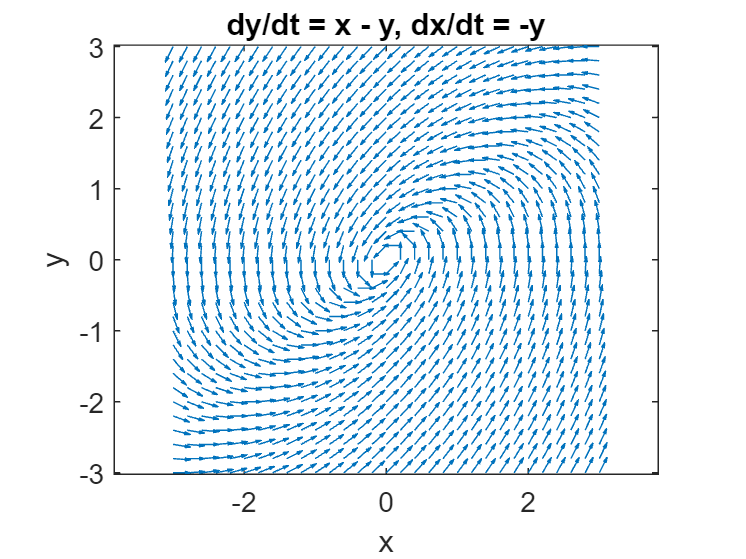

x = -3:0.2:3; 
y = -3:0.2:3;


[X, Y] = meshgrid(x, y);

U = -Y;
V = X - Y;

arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

figure
quiver(X, Y, U, V)
hold on

axis equal

title('dy/dt = x - y, dx/dt = -y')
xlabel('x')
ylabel('y')

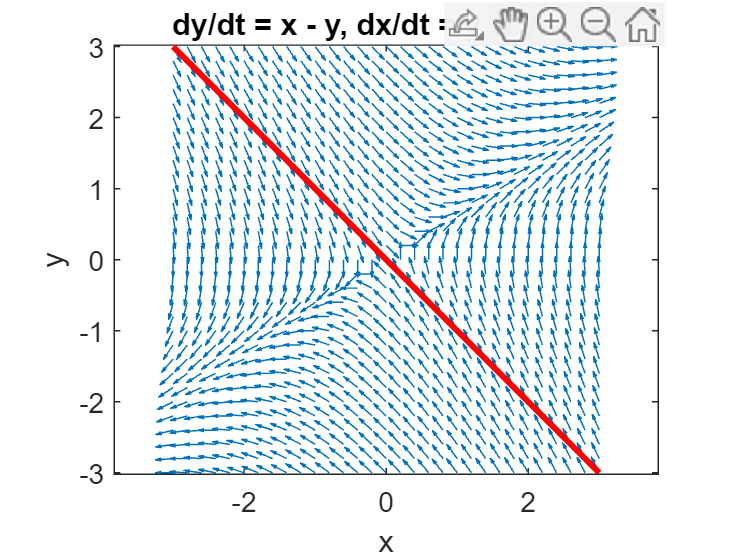

x = -3:0.2:3; 
y = -3:0.2:3;


[X, Y] = meshgrid(x, y);

U = Y;
V = X - Y;

arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

figure
quiver(X, Y, U, V)
hold on

plot(x, -x, 'r', 'LineWidth', 2);
hold off

axis equal

title('dy/dt = x - y, dx/dt = y & y = -x')
xlabel('x')
ylabel('y')